# Interactive biplot

#### Background 

The biplot is a simultaneous representation of the n units (rows of the data matrix) and the p variables (columns of the data matrix) in a two-dimensional space. The idea behind the biplot is to add the information about the relationship between variables to the graph of the principal component scores. The prefix "bi" in biplot indicates the two pieces of information contained in X and represented in the graph: the rows of X represent the sample observations, and the columns of X represent the variables. The construction of the biplot is based on the singular value decomposition (SVD) of the data matrix in terms of deviations from the mean  or the matrix of standardized deviations Z using just the first two singular values. In symbols


$$Z \approx \left[ (\sqrt{n-1})^\omega U_{(2)} \Gamma_{(2)}^\alpha \right]
  [ \Gamma_{(2)}^{1-\alpha}
    V_{(2)}' (\sqrt{n-1})^{1-\omega} ].$$


The n row points can be represented by the n × 2 matrix:


$$ \left[ (\sqrt{n-1})^\omega U_{(2)} \Gamma_{(2)}^\alpha \right]$$


and the p column points (arrows) by the 2 × p matrix:


$$[ \Gamma_{(2)}^{1-\alpha}  V_{(2)}' (\sqrt{n-1})^{1-\omega} ].$$


Naturally, the smaller ω is, the greater the length of the arrows, and the more compressed the coordinates of the row points become.

Representation A: when $\omega$ = 1 and $\alpha$ = 0,  row points are represented by standardized principal components and column points by arrows whose length represents the correlation between the original variables and the principal components.

Representation B: $\omega$ = 1 and $\alpha$ = 1, row points are represented by non-standardized principal components and column points by arrows whose length corresponds to the first two eigenvectors.

#### Example: interactive biplot for the citiesItaly dataset

load citiesItaly.mat
disp(citiesItaly.Properties.Description)

The citiesItaly dataset contains 107 records for the 107 provinces of Italy for seven indicators concerning the quality of life: The 7 variables are:
addedval = added value per capita
depost = amount of bank deposits per inhabitant
unemploy = unemployment rate
export = percentage of export divided by GNP of the province
bankrup = percentage of bankruptcy declarations on active companies
billsover = bills overdue indicator (percentage of bills protested on bills issued)
The data come from the Italian financial newspaper Il Sole 24 Ore, which every year produces the quality of life ranking of the Italian provinces.


In this file instead of calling pcaFS we call directly function biplotFS

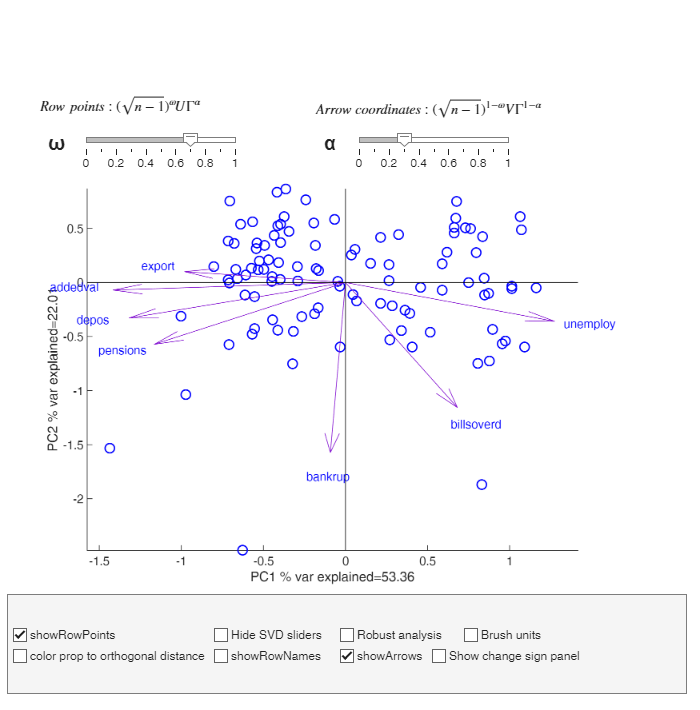

biplotFS(citiesItaly)

In the GUI, you can show/hide various components of the plot, and use the scrollbars to choose the values for the parameters α and ω for the singular value decomposition. The default option is ω = 0.7 and α = 0.3.

If $\omega$ = 1 and $\alpha$ = 0 is selected in the sliding bars

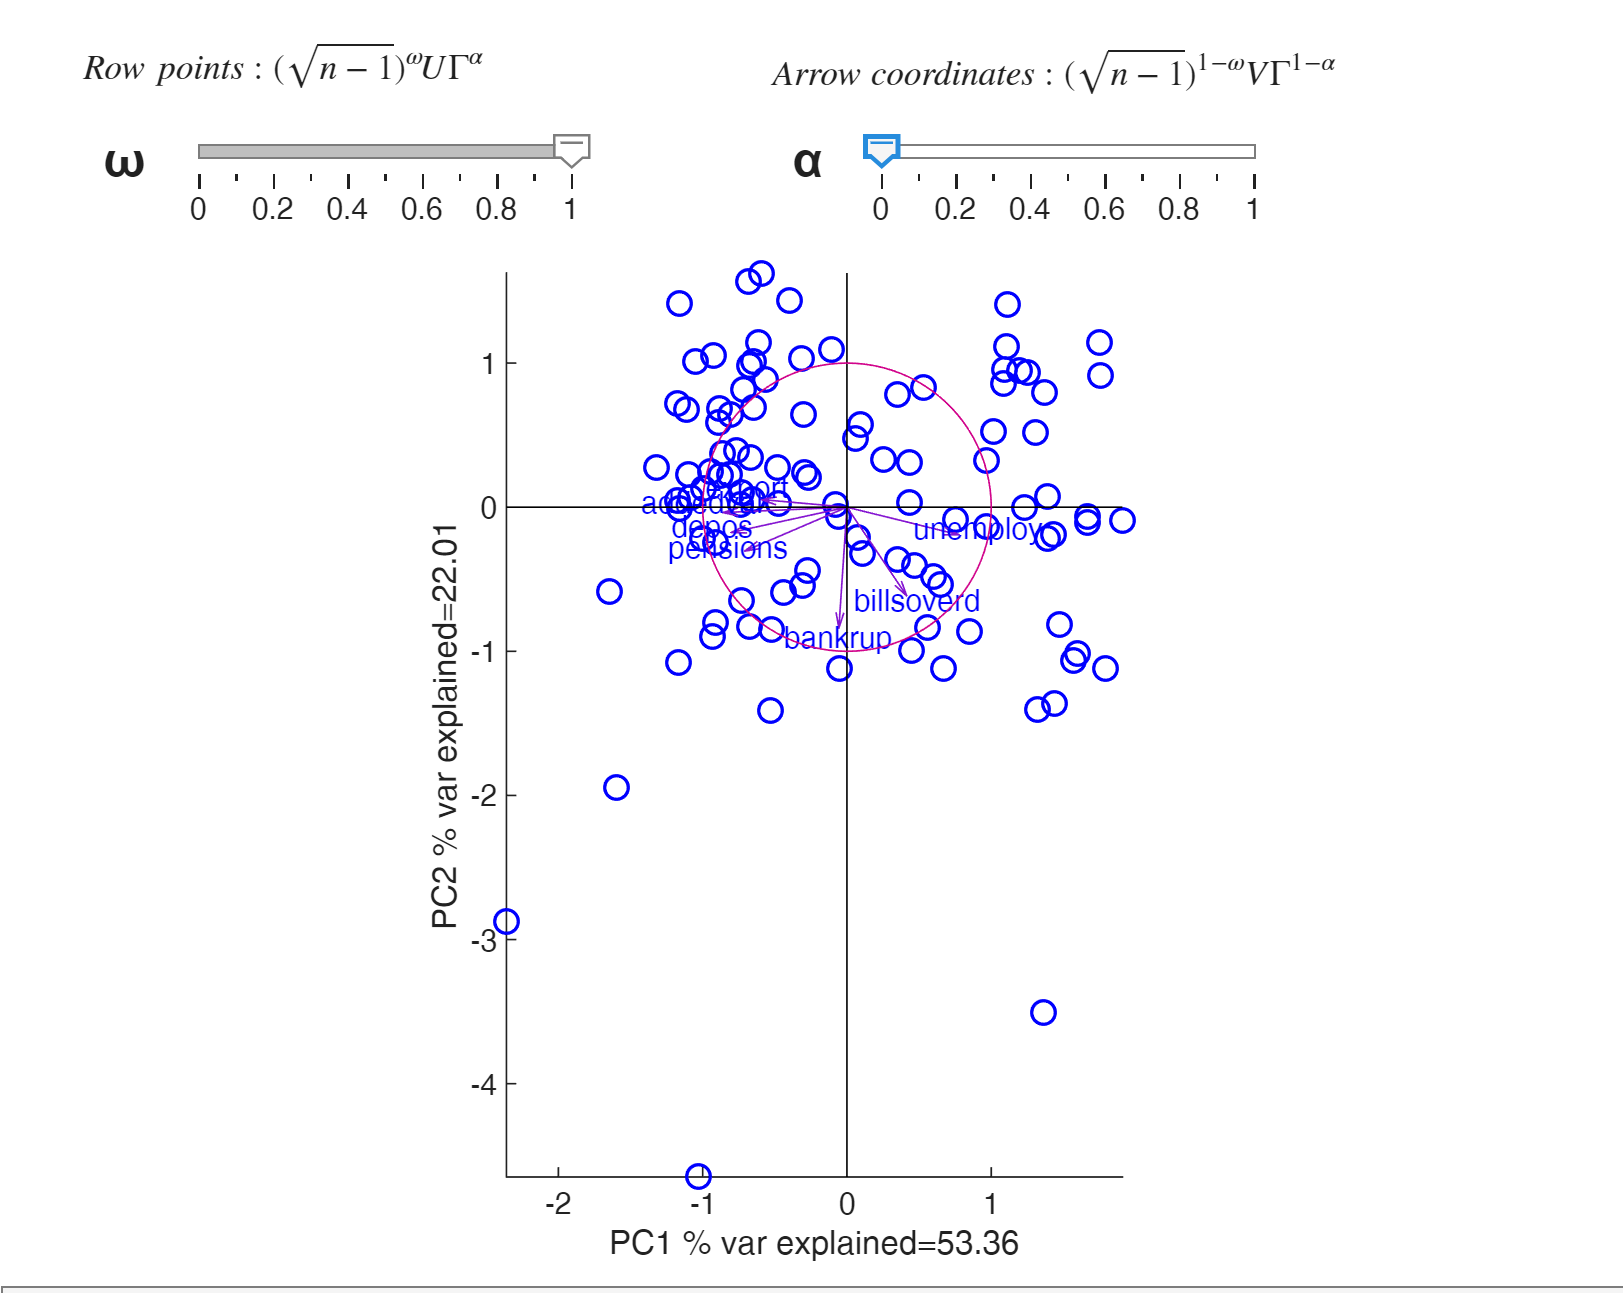

in the Command window the following message automatically appears

`When \omega=1 and \alpha=0`

`Row points represent standardized principal components sqrt(n-1)*U=ZV*\Gamma^-1`

`Arrows represent correlations between variables and principal components \Gamma*V`

`The length of the arrows is the communality of the variable`

`In this case the unit circle is also shown`

In summary, in representation A. the length of the arrow is exactly equal to the square root of the communality

(i.e., the square root of the portion of variance of the j-th variable explained by the first two principal components).

If $\omega$ = 1 and α = 1 is selected in the sliding bars 

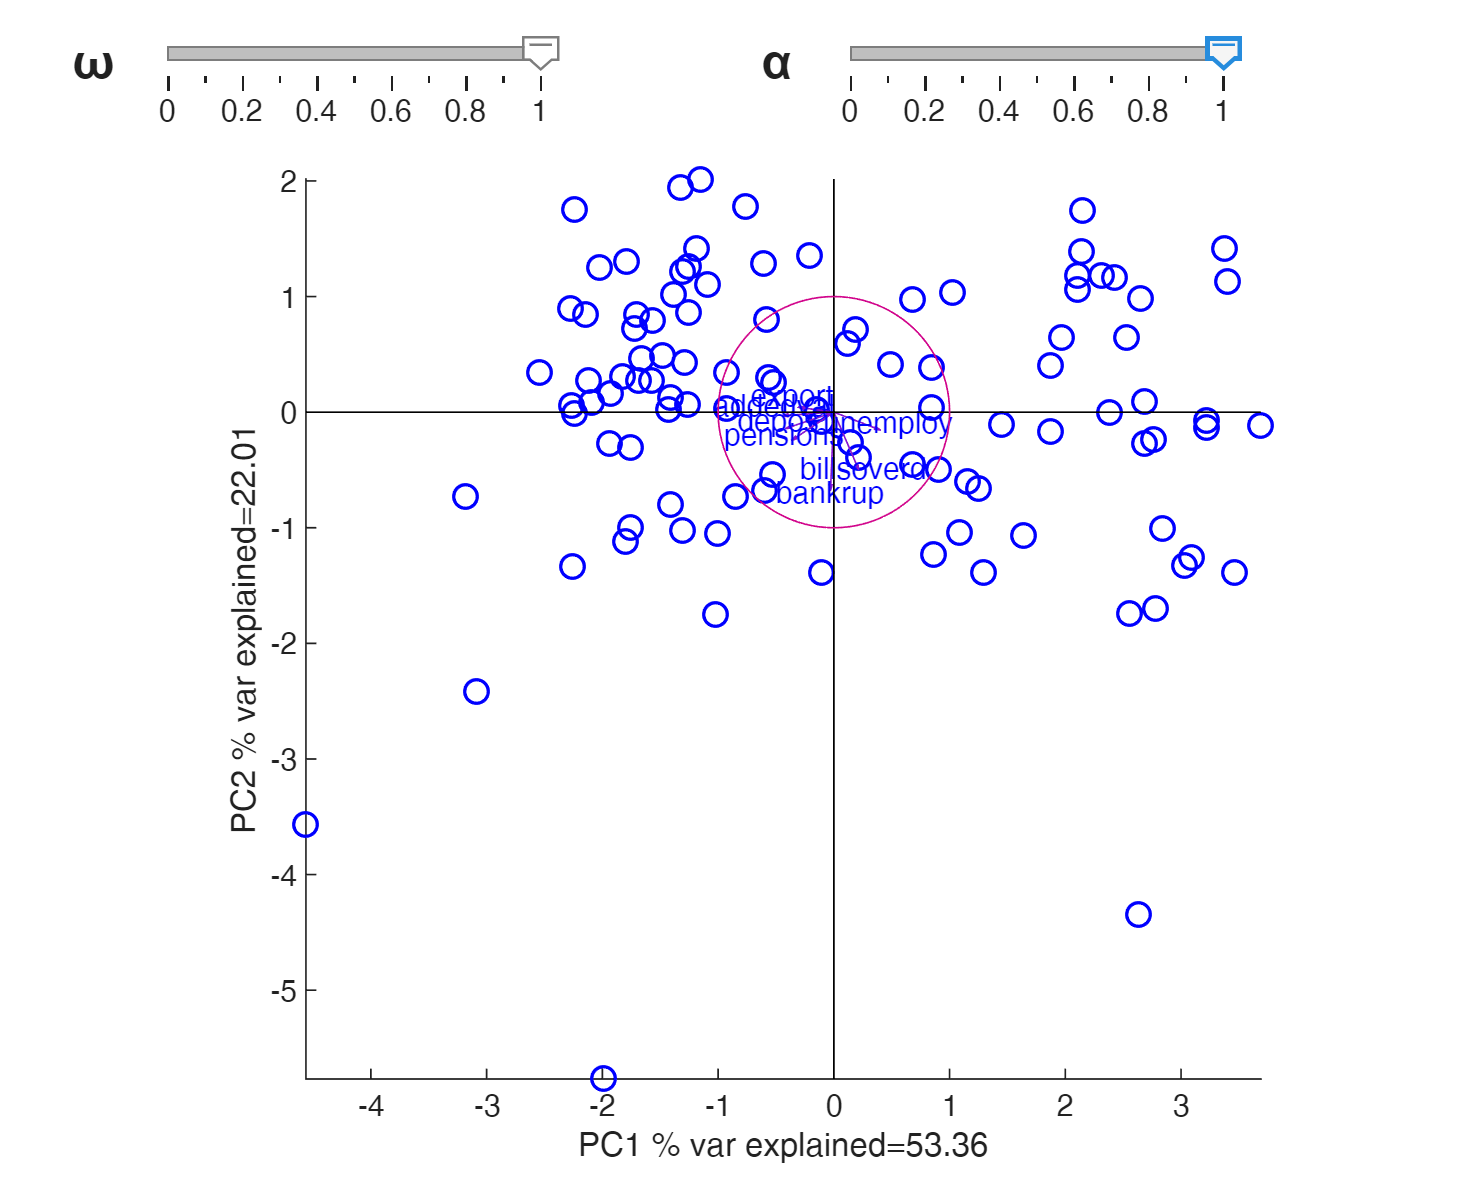

in the Command window the following message automatically appears

`When \omega=1 and \alpha=1`

`Row points represent principal components sqrt(n-1)*U*\Gamma=ZV`

`Arrows represent the eigenvectors V`

`In this case the unit circle is also shown`

In this representation (which we call B), the length of the arrows is not equal to the square root of the communality, but is merely "a function" of the communality.

If the checkbox "color prop to orthogonal distance" is selected,  the colorbar associated with the intensity of the orthogonal distance of the units automatically appears

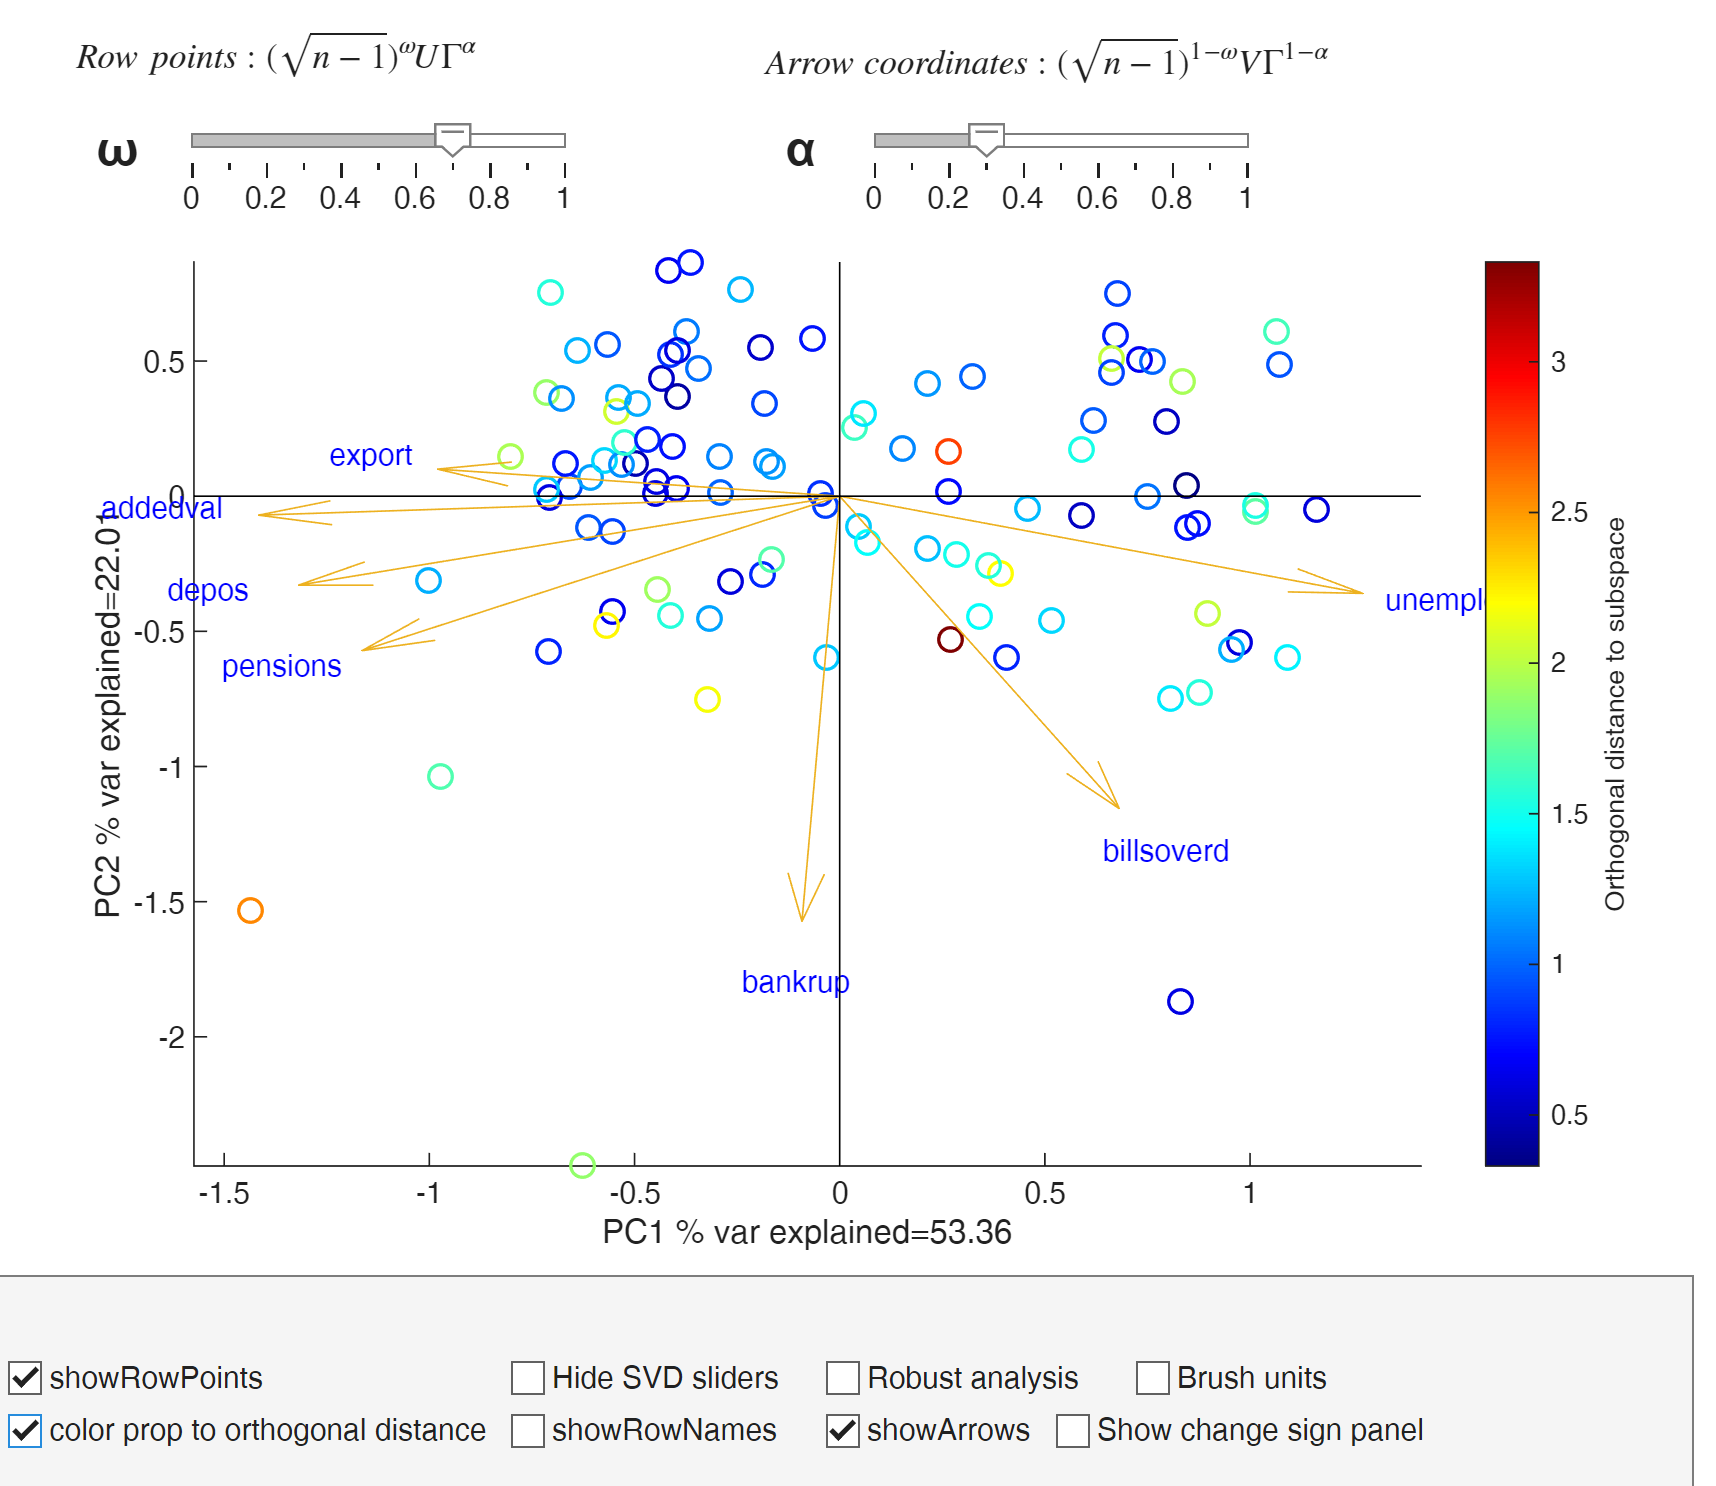

Clicking on the check box `showRowNames` it is possible to visualize all the names of the units.

If the checkbox `Brush units` is selected, once a rectangular region in the biplot has been selected, the scatterplot matrix with the selected units highlighted automatically appears

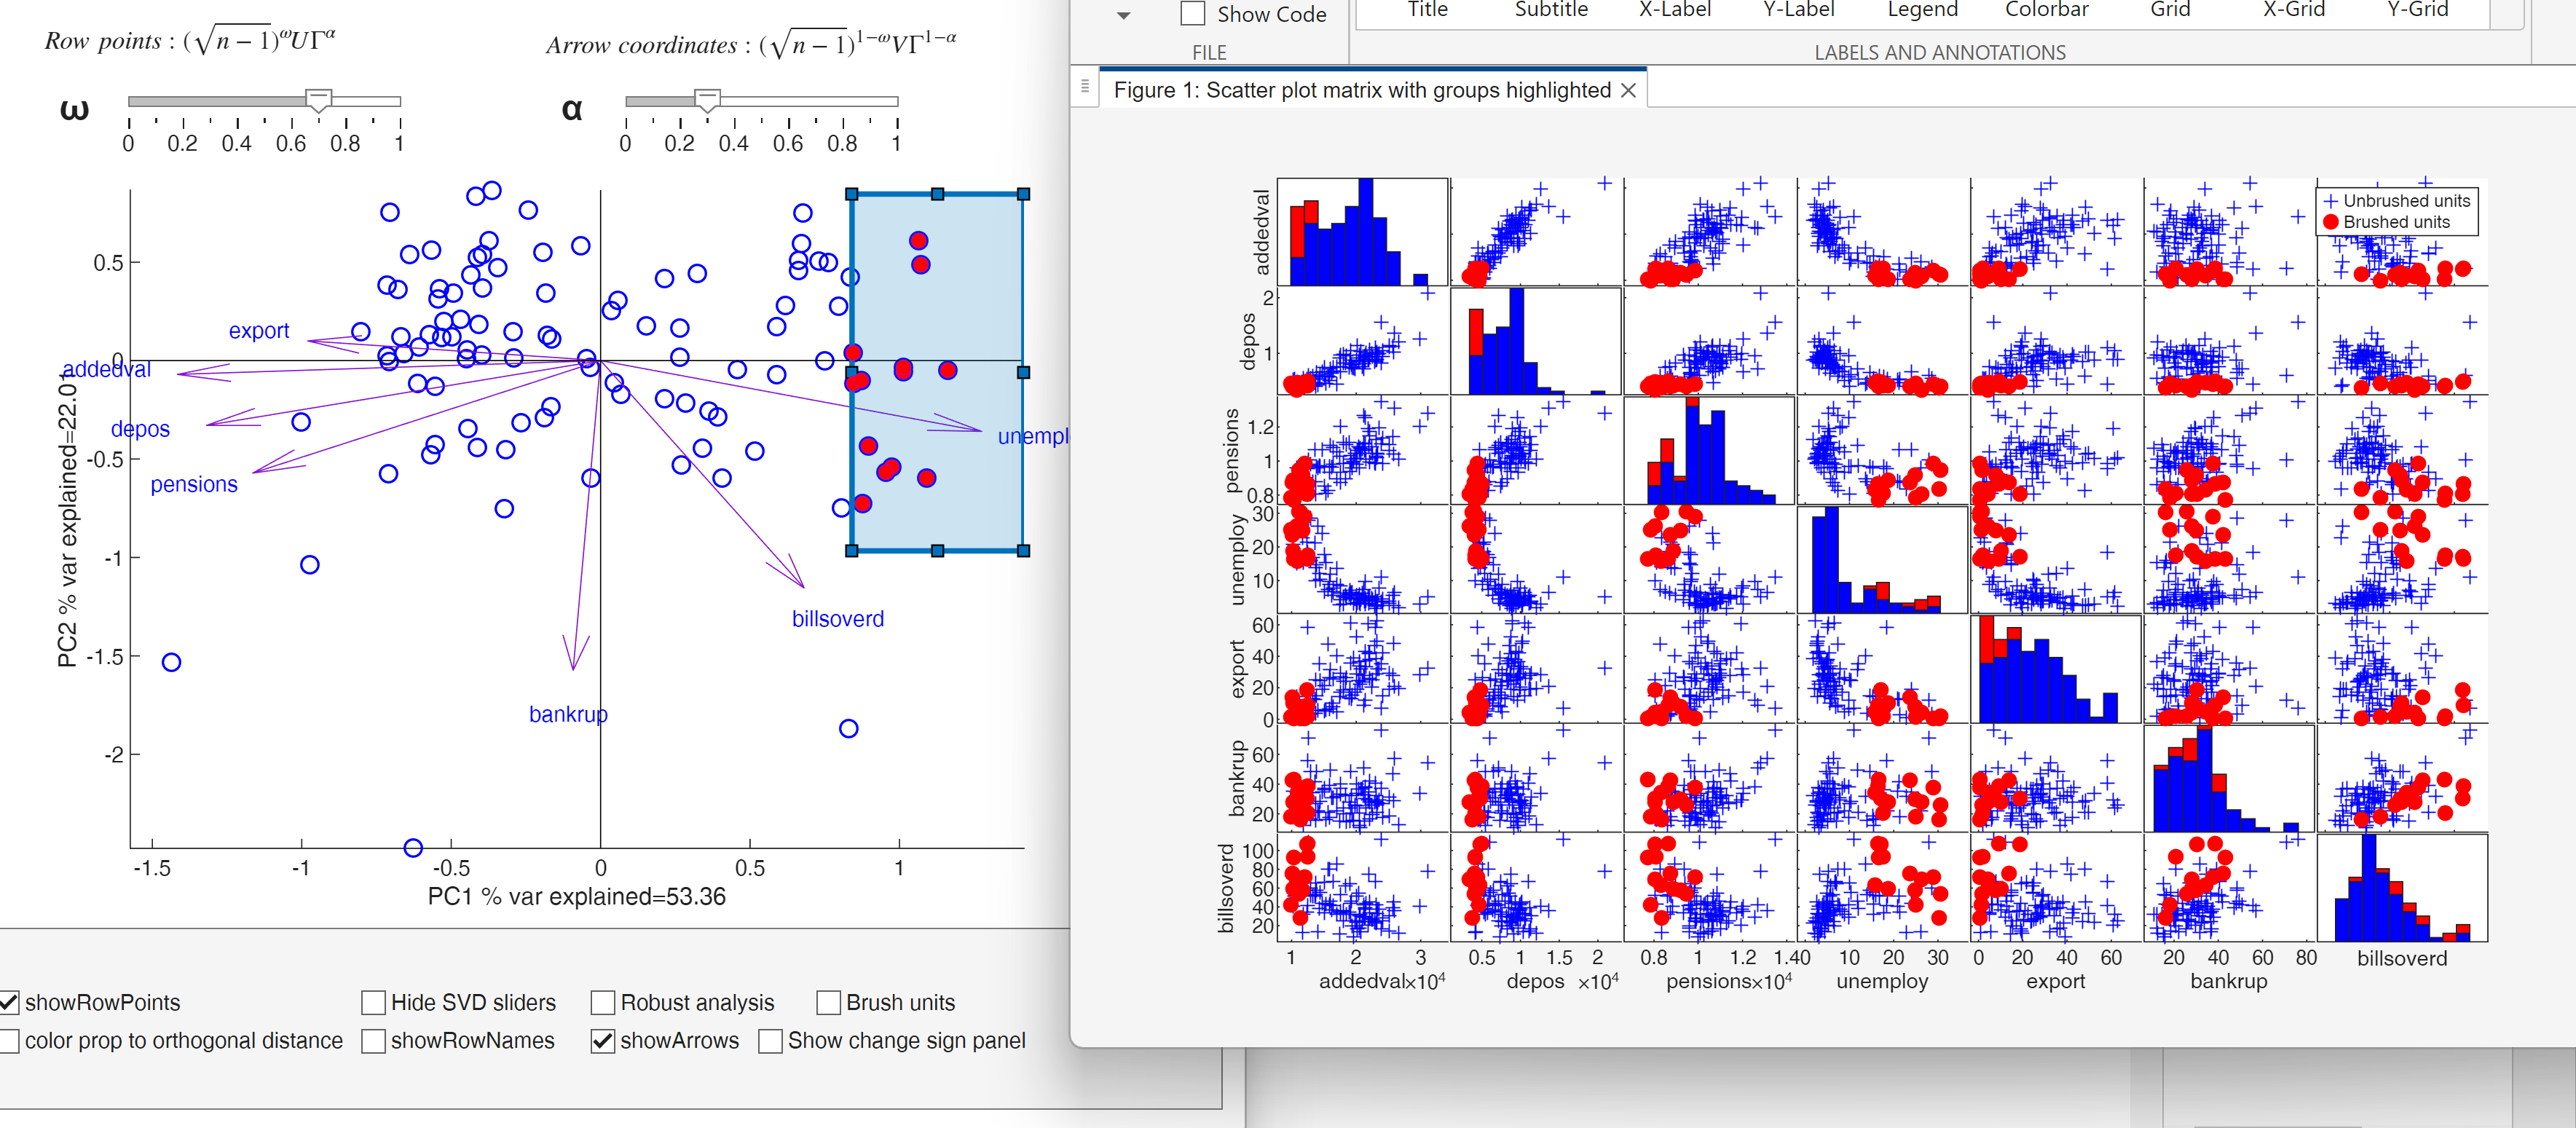

Remark: note that in order that the selection tools uses function [drawrectangle](https://www.mathworks.com/help/images/ref/drawrectangle.html) of the image processing toolbox therefore this toolbox has to be installed.